# **Fracture and Break Detection in Tibial X-Rays**

**Image Preperation and User Input**

clc; clear;
pixName = input('Please input the name of your X-Ray image without the format type : ', "s");
img = imread(strcat(pixName,'.jpg'));

**Region of Interest Selection and Preprocessing**

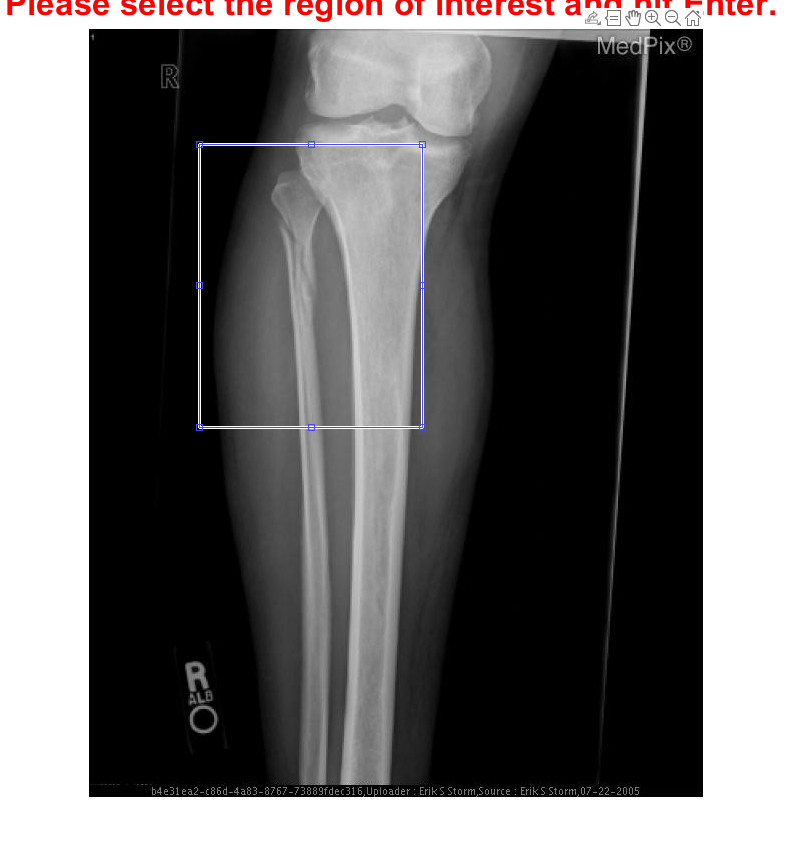

imshow(img);
title('Please select the region of interest and hit Enter. ', 'FontSize', 25, 'Color','r');
cropped = imrect();

position = cropped.getPosition();
position = round(position);
newImg = img(position(2) + (0:position(4)), position(1) + (0:position(3)));
newImg = imsharpen(newImg);
newImg(newImg < 100) = 0;

**Filtering and Edge Detection**

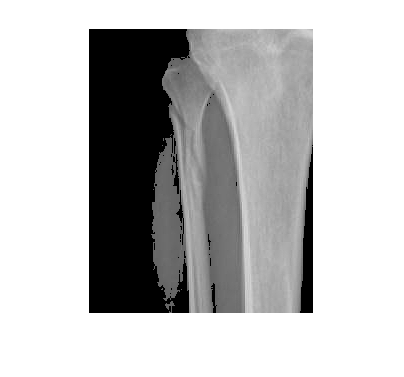

[~,threshold] = edge(newImg, 'canny');
fudgeFactor = .5;
BWs = edge(newImg,'canny',threshold*fudgeFactor);
se90 = strel('line',3,90);
se0 = strel('line',3,0);
BWsdil = imdilate(BWs,[se90 se0]);
BWdfill = imfill(BWsdil,'holes');
BWislands = bwareaopen(BWdfill,20000);
seD = strel('diamond',1);
BWfinal = imerode(BWislands,seD);
BWfinal = imerode(BWfinal,seD);
imshow(newImg);

**Rotation and Pixel Marking**

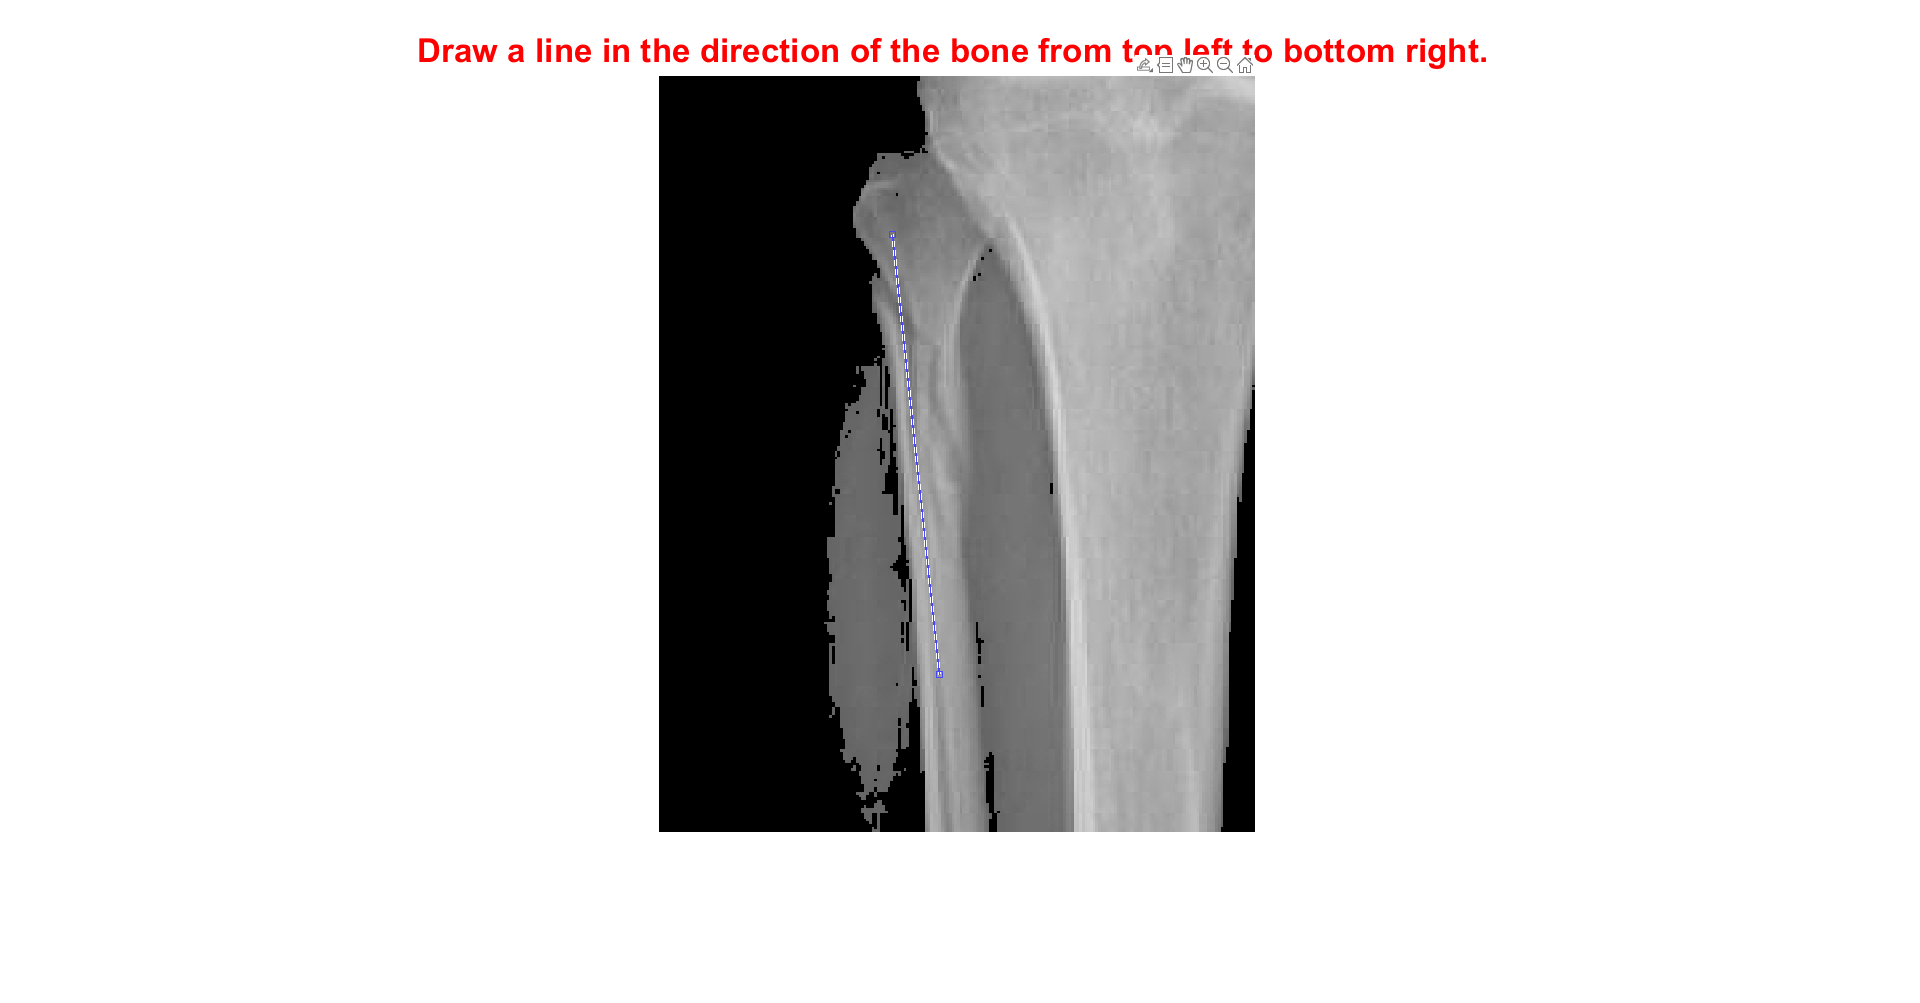

title('Draw a line in the direction of the bone from top left to bottom right. ', 'FontSize', 25, 'Color','r');
line = imline();

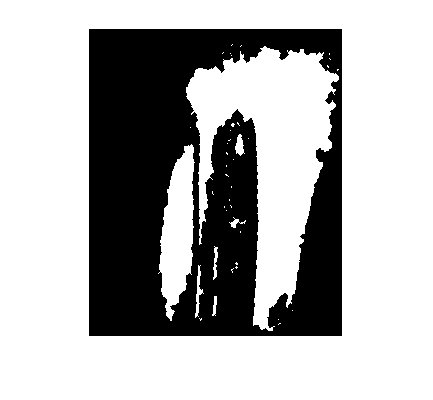

linePos = line.getPosition();
magLine = sqrt((linePos(1,1) - linePos(2,1))^2 + (linePos(1,2) - linePos(2,2))^2);
normLine = abs(linePos(1,2) - linePos(2,2));
degrees = acosd(normLine/magLine);
BWfinal = imrotate(BWfinal, -real(degrees));
imshow(BWfinal);

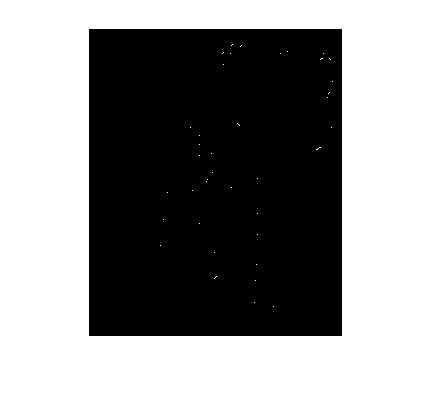


markedPix = zeros(size(BWfinal));
for(i = 1:1:size(BWfinal,1)-20)
    for(j = 1:1:size(BWfinal,2))
        if BWfinal(i,j) == 1 && BWfinal(i+20,j) == 1 && BWfinal(i+1,j) == 0 && BWfinal(i+2,j) == 0 && BWfinal(i+3,j) == 0 && BWfinal(i+4,j) == 0
            markedPix(i,j) = 1;
        end
    end
end
imshow(markedPix);

**Marked Pixel Mean Calculation**

sumX = 0;
sumY = 0;
counter = 0;
for(i = 1:1:size(markedPix,1))
    for(j = 1:1:size(markedPix,2))
        if markedPix(i,j) == 1
            sumX = sumX + j;
            sumY = sumY + i;
            counter = counter + 1;
        end
    end
end
averageX = round(sumX/counter);
averageY = round(sumY/counter);

**Final Prediction Placement and Display**

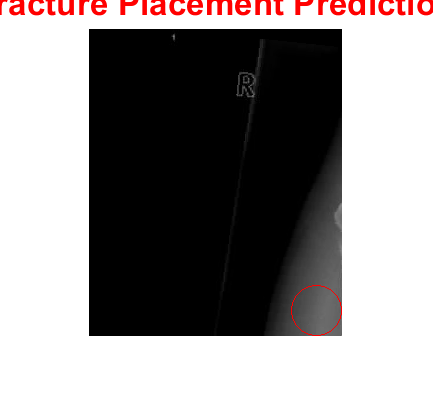

rotatedFinalImg = imrotate(img, -real(degrees));
r = 25;
x = position(1) + averageY;
y = position(2) + averageX;
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
hold on;
imshow(rotatedFinalImg);
h = plot(xunit, yunit, "Color", 'r');
title('Fracture Placement Prediction','FontSize', 25, 'Color','r');
hold off;